# Evaluation of the trained models

In this section we test additionally trained models with data from 2019 and 2020 (Real Time) as well as we plot response vs predicted plot for some of the models. To plot learning curves, model training code has been exported from the toolbox and modified to train the model in a for loop catching different amount of training data examples (m). We include two files for learning curves plot as examples of what it is necessary to change in the code to make the plot:

wind_svm1_learningCurves.m

wind_gpr2_learningCurves.m

## Wind speed forecasting in time domain

### Linear Regression

h_wind1 = wind_lr2.predictFcn(dataWind2019_shortTerm(:,{'WSPDt_6','WSPDt_5','WSPDt_4','WSPDt_3','WSPDt_2','WSPDt_1'}))

h_wind1 =     7.8424
    6.6597
    6.5352
    6.9930
    8.0209
    7.7768
    6.2869
    5.6980
    6.0521
    7.0716


RMSE_wind_lr = error(h_wind1, dataWind2019_shortTerm.WSPD)

RMSE_wind_lr = 1.1237

h_wind1_2 = wind_lr2.predictFcn(dataWindRT_shortTerm(:,{'WSPDt_6','WSPDt_5','WSPDt_4','WSPDt_3','WSPDt_2','WSPDt_1'}));
RMSE_wind_lr2 = error(h_wind1_2, dataWindRT_shortTerm.WSPD) 

RMSE_wind_lr2 = 1.1723

wind_lr2

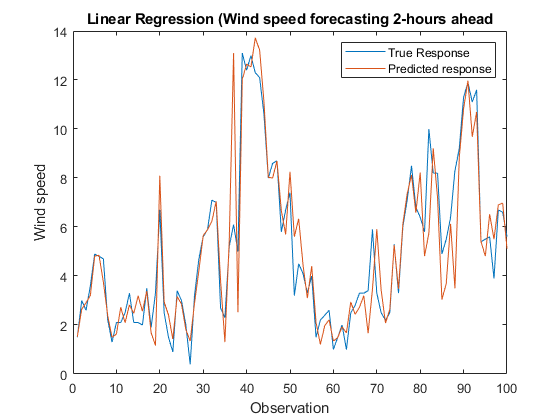

m = 1:1:100;
plot(m,validationResponse(1:100),m,validationPredictions(1:100))
title('Linear Regression (Wind speed forecasting 2-hours ahead')
xlabel('Observation')
ylabel('Wind speed')
legend('True Response','Predicted response')

### Support Vector Regression

h_wind2 = wind_svm3.predictFcn(dataWind2019_st14(:,{'WSPDt_14','WSPDt_13','WSPDt_12','WSPDt_11','WSPDt_10','WSPDt_9','WSPDt_8','WSPDt_7','WSPDt_6','WSPDt_5','WSPDt_4','WSPDt_3','WSPDt_2','WSPDt_1'}));
RMSE_wind_svm3_2019 = error(h_wind2, dataWind2019_st14.WSPD)

RMSE_wind_svm3_2019 = 1.1462

h_wind2_2 = wind_svm3.predictFcn(dataWindRealTime_st14(:,{'WSPDt_14','WSPDt_13','WSPDt_12','WSPDt_11','WSPDt_10','WSPDt_9','WSPDt_8','WSPDt_7','WSPDt_6','WSPDt_5','WSPDt_4','WSPDt_3','WSPDt_2','WSPDt_1'}));
RMSE_wind_svm3_RealTime = error(h_wind2_2, dataWindRealTime_st14.WSPD)

RMSE_wind_svm3_RealTime = 1.1722

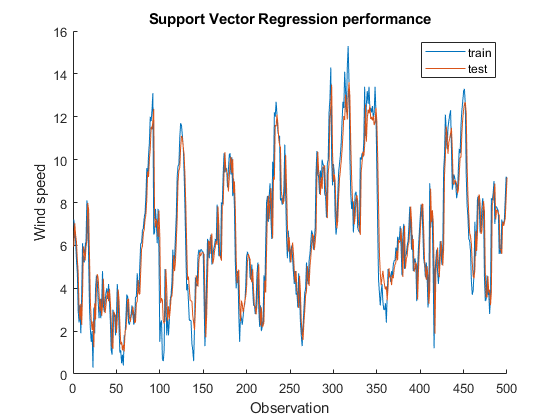

clf;
hold on
plot(1:500,dataWind2019_st14.WSPD(1:500,1))
plot(1:500,h_wind2(1:500))
legend('train','test')
title('Support Vector Regression performance')
xlabel('Observation')
ylabel('Wind speed')
hold off

### GPR

h_wind = wind_gpr1.predictFcn(dataWind2019_st1(:,{'WSPDt_1'}));
RMSE_wind_gpr(1,1) = error(h_wind, dataWind2019_st1.WSPD)

RMSE_wind_gpr = 1.1274

h_wind4_2 = wind_gpr1.predictFcn(dataWindRealTime_st1(:,{'WSPDt_1'}));
RMSE_wind_gpr(1,2) = error(h_wind4_2, dataWindRealTime_st1.WSPD)

RMSE_wind_gpr =     1.1274    1.1721


h_wind = wind_gpr2.predictFcn(dataWind2019_st1(:,{'WSPDt_1','PRESt_1','ATMPt_1'}));
RMSE_wind_gpr(2,1) = error(h_wind, dataWind2019_st1.WSPD)
h_wind4_2 = wind_gpr2.predictFcn(dataWindRealTime_st1(:,{'WSPDt_1','PRESt_1','ATMPt_1'}));
RMSE_wind_gpr(2,2) = error(h_wind4_2, dataWindRealTime_st1.WSPD)


plot(m,validationResponse_windgpr2(1:100),m,validationPredictions_windgpr2(1:100))
title('GPR(wind\_gpr2 model)')
xlabel('Observation')
ylabel('Wind speed')
legend('True Response','Predicted response')

h_wind = wind_gpr3.predictFcn(dataWind2019_st3);
RMSE_wind_gpr(3,1) = error(h_wind, dataWind2019_st3.WSPD)
h_wind4_2 = wind_gpr3.predictFcn(dataWindRealTime_st3);
RMSE_wind_gpr(3,2) = error(h_wind4_2, dataWindRealTime_st3.WSPD)

### **Artificial Neural Network**

wind_nar1

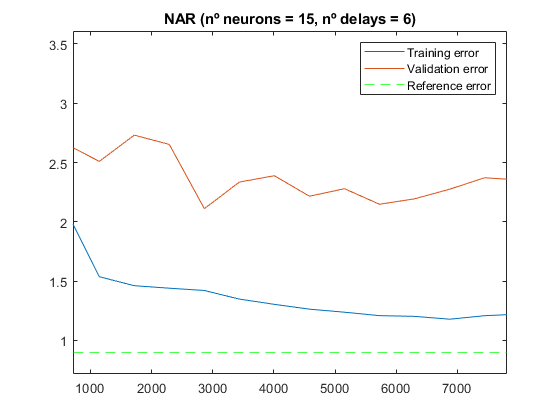

clf;
gap = size(predictorsWind2018,1)/15;
m = 1:gap:size(predictorsWind2018,1);
plot(m,RMSE_windnar1(:,1),m,RMSE_windnar1(:,2))
title('NAR (nº neurons = 15, nº delays = 6)')
xlim([5 size(targetsWind2018,2)])
yline(0.9,'--green')
legend('Training error', 'Validation error','Reference error')

wind_narx1

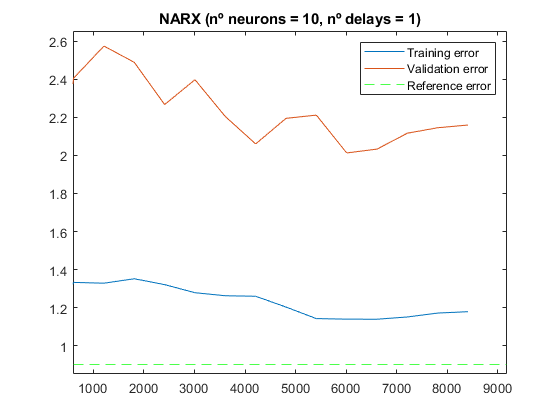

clf;
m=10:600:size(targetsWind2018,2);
plot(m,RMSE_windnarxprueba(:,1),m,RMSE_windnarxprueba(:,2));
title('NARX (nº neurons = 10, nº delays = 1)')
xlim([5 size(targetsWind2018,2)])
yline(0.9,'--green')
legend('Training error', 'Validation error','Reference error')

## **Significant wave height forecasting in frecuency domain**

**Linear Regression**

waves_lr1

h_waves = waves_lr1.predictFcn(data2019(:,{'WSPD'}));
RMSE_waves(1,1) = error(h_waves, data2019.WVHT);
h_waves2 = waves_lr1.predictFcn(dataRealTime(:,{'WSPD'}));
RMSE_waves(1,2) = error(h_waves2, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692


h_waves = waves_lr2.predictFcn(data2019(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(2,1) = error(h_waves, data2019.WVHT);
h_waves2 = waves_lr2.predictFcn(dataRealTime(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(2,2) = error(h_waves2, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692


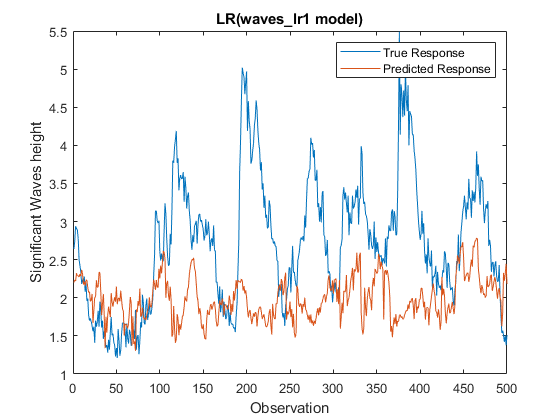

m = 1:1:500;
plot(m,table2array(data2019(1:500,{'WVHT'})),m,h_waves(1:500,:))
title('LR(waves\_lr1 model)')
xlabel('Observation')
ylabel('Significant Waves height')
legend('True Response','Predicted Response')

waves_lr2

h_waves2= waves_lr2.predictFcn(data2019(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(2,1) = error(h_waves2, data2019.WVHT);
h_waves22 = waves_lr2.predictFcn(dataRealTime(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(2,2) = error(h_waves22, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692


waves_svm2 

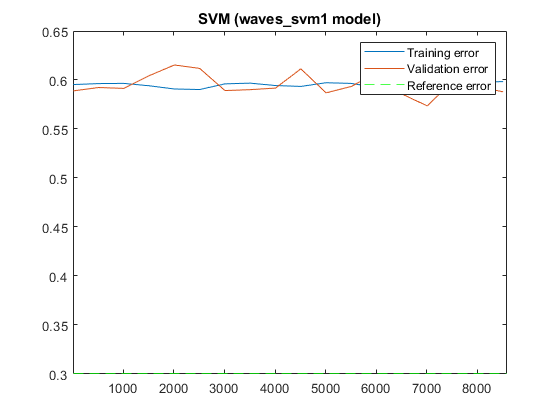

m = 10:500:size(data2018,1);
plot(m,RMSE_wavessvm1(:,1),m,RMSE_wavessvm1(:,2))
title('SVM (waves\_svm1 model)')
xlim([5 size(data2018,1)])
yline(0.3,'--green')
legend('Training error', 'Validation error','Reference error')

h_waves3= waves_svm1.predictFcn(data2019(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(3,1) = error(h_waves3, data2019.WVHT);
h_waves3 = waves_svm1.predictFcn(dataRealTime(:,{'WSPD','MWD','WDIR'}));
RMSE_waves(3,2) = error(h_waves3, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692
    0.8159    0.5755


h_waves4= waves_svm2.predictFcn(data2019(:,{'WSPD','MWD','WDIR','WTMP'}));
RMSE_waves(4,1) = error(h_waves4, data2019.WVHT);
h_waves42 = waves_svm2.predictFcn(dataRealTime(:,{'WSPD','MWD','WDIR','WTMP'}));
RMSE_waves(4,2) = error(h_waves42, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692
    0.8159    0.5755
    0.8170    0.6149


h_waves5= waves_svm3.predictFcn(data2019(:,{'WSPD','MWD','WDIR','WTMP','PRES'}));
RMSE_waves(5,1) = error(h_waves5, data2019.WVHT);
h_waves52 = waves_svm3.predictFcn(dataRealTime(:,{'WSPD','MWD','WDIR','WTMP','PRES'}));
RMSE_waves(5,2) = error(h_waves52, dataRealTime.WVHT)

RMSE_waves =     0.8209    0.6323
    0.7877    0.5692
    0.8159    0.5755
    0.8170    0.6149
    0.8019    0.7017


## Misalignment forecasting in the time domain

h_mis1_2019 = mis_lr1.predictFcn(dataMis2019_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(1,1) = error(h_mis1_2019, dataMis2019_st1.MIS)

RMSE_mis = 64.0865

h_mis1_Real = mis_lr1.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(1,2) = error(h_mis1_Real, dataMisRealTime_st1.MIS)

RMSE_mis =    64.0865   66.4444


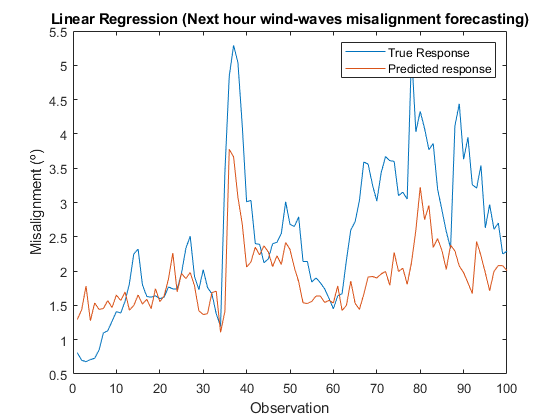

m = 1:1:100;
plot(m,validationResponse(1:100),m,validationPredictions(1:100))
title('Linear Regression (Next hour wind-waves misalignment forecasting)')
xlabel('Observation')
ylabel('Misalignment (º)')
legend('True Response','Predicted response')

h_mis1_2019 = mis_svm1.predictFcn(dataMis2019_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(2,1) = error(h_mis1_2019, dataMis2019_st1.MIS)
h_mis1_Real = mis_svm1.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(2,2) = error(h_mis1_Real, dataMisRealTime_st1.MIS)


clf;
plot(m,RMSE_mis_svm1(:,1),m,RMSE_mis_svm1(:,2))
title('Medium Gaussian SVM')
xlim([5 size(dataMis2018_st1,1)])
yline(45,'--green')
legend('Training error', 'Validation error','Reference error')

It could be suffering from high bias: try a more complex model or getting more features could help (we will try in next session) -> And it woooorks

h_mis1_2019 = mis_gpr2.predictFcn(dataMis2019_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(4,1) = error(h_mis1_2019, dataMis2019_st1.MIS)
h_mis1_Real = mis_gpr2.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(4,2) = error(h_mis1_Real, dataMisRealTime_st1.MIS)

Mis_gpr1 plots:

m = 1:1:100;
plot(m,validationResponse(1:100),m,validationPredictions(1:100))
title('GPR (Next hour misalignment forecasting)')
xlabel('Observation')
ylabel('Misalignment (º)')
legend('True Response','Predicted response')

h_mis1_2019 = mis_svm2.predictFcn(dataMis2019_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(10,1) = error(h_mis1_2019, dataMis2019_st1.MIS)
h_mis1_Real = mis_svm2.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','WSPD_t1','PRES_t1','WTMP_t1','APD_t1'}));
RMSE_mis(10,2) = error(h_mis1_Real, dataMisRealTime_st1.MIS)

m = 1:1:100;
plot(m,validationResponse(1:100),m,validationPredictions(1:100))
title('SVM (Next hour misalignment forecasting)')
xlabel('Observation')
ylabel('Misalignment (º)')
legend('True Response','Predicted response')

Session 2: we used as predictors: MIS_t1, APD_t1, PRES_t1, WTMP_t1, WSPD_t1

Gaussian Process Regression: the best configuration: Rational Quadratic GPR

h_mis1_2019 = mis_gpr3.predictFcn(dataMis2019_st1(:,{'MIS_t1','APD_t1','PRES_t1','WTMP_t1','WSPD_t1'}));
RMSE_mis(5,1) = error(h_mis1_2019, dataMis2019_st1.MIS)
h_mis1_Real = mis_gpr3.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','APD_t1','PRES_t1','WTMP_t1','WSPD_t1'}));
RMSE_mis(5,2) = error(h_mis1_Real, dataMisRealTime_st1.MIS)

h_mis2_2019 = mis_lr2.predictFcn(dataMis2019_sT6(:,{'MISt_1','MISt_2','MISt_3','MISt_4','MISt_5','MISt_6'}));
RMSE_mis(6,1) = error(h_mis2_2019, dataMis2019_sT6.MIS)
h_mis2_Real = mis_lr2.predictFcn(dataMisRealTime_sT6(:,{'MISt_1','MISt_2','MISt_3','MISt_4','MISt_5','MISt_6'}));
RMSE_mis(6,2) = error(h_mis2_Real, dataMisRealTime_sT6.MIS)

h_mis2_2019 = mis_lr3.predictFcn(dataMis2019_st1(:,{'MIS_t1','WTMP_t1','WSPD_t1','PRES_t1'}));
RMSE_mis(7,1) = error(h_mis2_2019, dataMis2019_st1.MIS)
h_mis2_Real = mis_lr3.predictFcn(dataMisRealTime_st1(:,{'MIS_t1','WTMP_t1','WSPD_t1','PRES_t1'}));
RMSE_mis(7,2) = error(h_mis2_Real, dataMisRealTime_st1.MIS)

Mis_lr3 plot

m = 1:1:100;
plot(m,validationResponse(1:100),m,validationPredictions(1:100))
title('Linear Regression (Next hour misalignment forecasting)')
xlabel('Observation')
ylabel('Misalignment (º)')
legend('True Response','Predicted response')

mis_narx2

clf;
plot(RMSE_mis_narx2(:,1),RMSE_mis_narx2(:,2),RMSE_mis_narx2(:,1),RMSE_mis_narx2(:,3))
title('NARX: mis_narx2 (nº neurons = 10, nº delays = 2)')
yline(50,'--green')
legend('Training error', 'Validation error','Reference error')

function [e] = error(h,y)
    isNotMissing = ~isnan(h) & ~isnan(y);
    e = sqrt(nansum(( h - y ).^2) / numel(y(isNotMissing) ));
end